**Diseño de control PID para el Intercovamex H2**

Modelo completo: motor DC + válvula + cámara + MFC + Pirani

clc;
s = tf('s');

%% PARÁMETROS DEL MOTOR JGA25-371 (de datasheet y mediciones) 
Ra  = 8.28;        % Ohm
La  = 5e-4;        % H
Kt  = 0.508;       % N·m/A
Kb  = 0.229;       % V·s/rad
Jeq = 1.5e-4;      % kg·m² (reflejada con carga)
beq = 8.0e-4;      % N·m·s/rad
N   = 34;          % Relación de engranaje del JGA25-371
Jvalv = 3.5e-5;    % inercia adicional del eje válvula
Jtot = Jeq + Jvalv / N^2;
btot = beq + 2e-3 / N^2; % fricción equivalente

%% PARÁMETROS DE LA CÁMARA DE VACÍO (manual Intercovamex H2) 
V = 12            % Volumen cámara ~12 litros

V = 12

S0 = 300;         % l/s – velocidad efectiva de bombeo base
kc = 20;          % l/s – pérdidas o fugas efectivas
a2 = (S0 + kc)/V % constante de tiempo equivalente de la cámara

a2 = 26.6667


%% PARÁMETROS DE LA VÁLVULA Y CONDUCTANCIA 
Salpha = 0.5 * S0;       % sensibilidad de conductancia a la apertura
k_alpha = 0.017;         % radianes de válvula por grado de motor
P0 = 5e-3;               % presión base en Torr (~6.6 Pa)

%%  MODELO MOTOR–VÁLVULA 

a1 = (Ra*btot + Kt*Kb)/(Ra*Jtot)

a1 = 98.9899

K_m = Kt/(N*Ra*Jtot);
K = -(P0 * Salpha * k_alpha * Kt) / (V * N * Ra * Jtot)

K = -0.0128


% Función de transferencia combinada:
Gp = K / (s * (s + a1) * (s + a2))

Gp =
 
          -0.01278
  ------------------------
  s^3 + 125.7 s^2 + 2640 s
 
Continuous-time transfer function.
Model Properties


Análisis en open loop

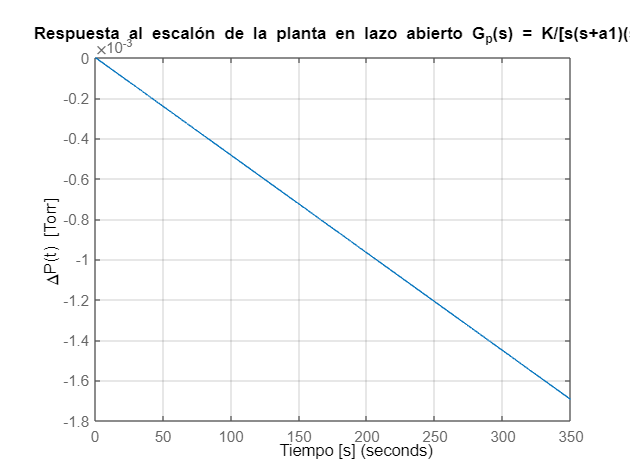

%% RESPUESTA AL ESCALÓN LAZO ABIERTO
figure; step(Gp); grid on;
title('Respuesta al escalón de la planta en lazo abierto G_p(s) = K/[s(s+a1)(s+a2)]');
ylabel('\DeltaP(t) [Torr]'); xlabel('Tiempo [s]');

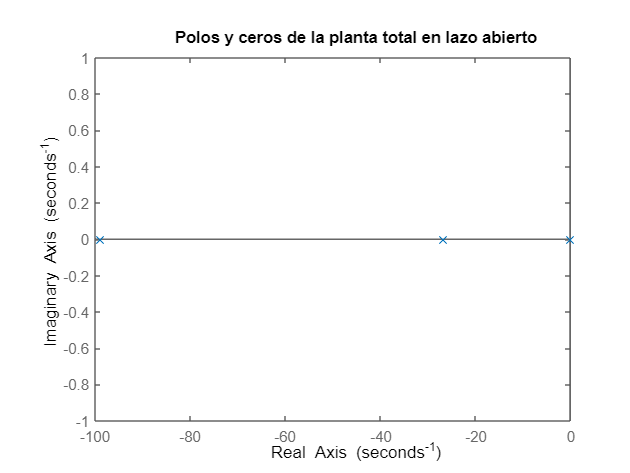


% Polos y ceros
figure; pzmap(Gp); title('Polos y ceros de la planta total en lazo abierto');

PID con autotunning

%% DISEÑO DEL PID (autotuning MATLAB con menor sobreimpulso)
% Ajuste más amortiguado (mayor margen de fase)
opts = pidtuneOptions('DesignFocus','reference-tracking','PhaseMargin',70);  % puedes probar 70–75°

% Opción 1: dejar que MATLAB elija la frecuencia de cruce automáticamente
[Cpid,info] = pidtune(Gp,'PID',[],opts);

% --- Si el sobreimpulso sigue alto, descomenta las 2 líneas siguientes ---
% wc = info.CrossoverFrequency * 0.6;        % cruce más bajo → más amortiguado
% [Cpid,info] = pidtune(Gp,'PID',wc,opts);

fprintf('PID Autotune (PM=%.1f°) → Kp=%.4f, Ki=%.4f, Kd=%.4f\n', ...
        info.PhaseMargin, Cpid.Kp, Cpid.Ki, Cpid.Kd);

PID Autotune (PM=70.0°) → Kp=-8931239.9935, Ki=-7165051.1347, Kd=-435128.9169



% Construcción del lazo abierto y cerrado
L = Cpid * Gp;
FTc = feedback(L, 1)

FTc =
 
           5561 s^2 + 1.141e05 s + 9.156e04
  --------------------------------------------------
  s^4 + 125.7 s^3 + 8200 s^2 + 1.141e05 s + 9.156e04
 
Continuous-time transfer function.
Model Properties



% Verificación rápida de estabilidad y métricas básicas
disp('isstable(FTc) = '); disp(isstable(FTc));

isstable(FTc) = 
   1



info_step = stepinfo(FTc);
fprintf('Rise=%.3f s, Ts=%.3f s, Overshoot=%.2f %%\n', ...
        info_step.RiseTime, info_step.SettlingTime, info_step.Overshoot);

Rise=0.031 s, Ts=0.048 s, Overshoot=1.57 %


Análisis lazo cerrado

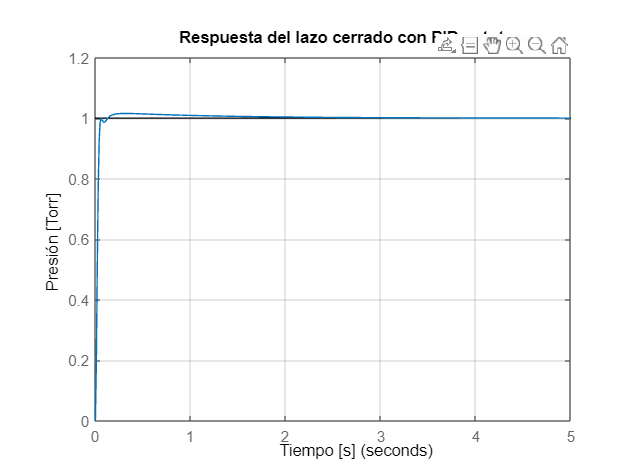

%% RESPUESTA AL ESCALÓN DE PRESIÓN  LAZO CERRADO
t = 0:0.01:5;
figure; step(FTc, t);
grid on; title('Respuesta del lazo cerrado con PID autotune');
xlabel('Tiempo [s]'); ylabel('Presión [Torr]');

stepinfo(FTc)

ans = struct with fields:
         RiseTime: 0.0307
    TransientTime: 0.0477
     SettlingTime: 0.0477
      SettlingMin: 0.9026
      SettlingMax: 1.0157
        Overshoot: 1.5683
       Undershoot: 0
             Peak: 1.0157
         PeakTime: 0.3115


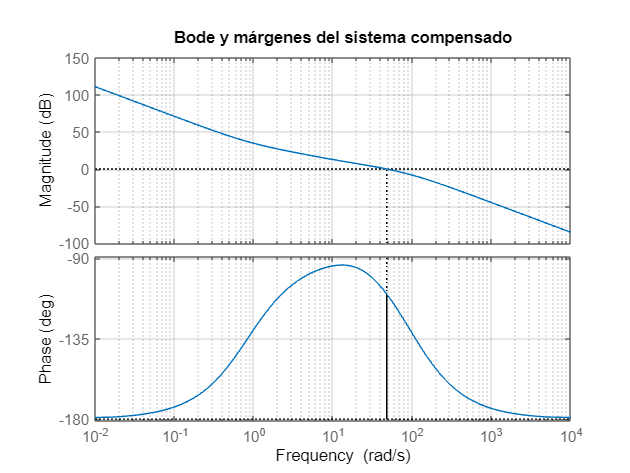


%% ANÁLISIS DE ESTABILIDAD LAZO CERRADO
figure; margin(L); grid on; title('Bode y márgenes del sistema compensado');

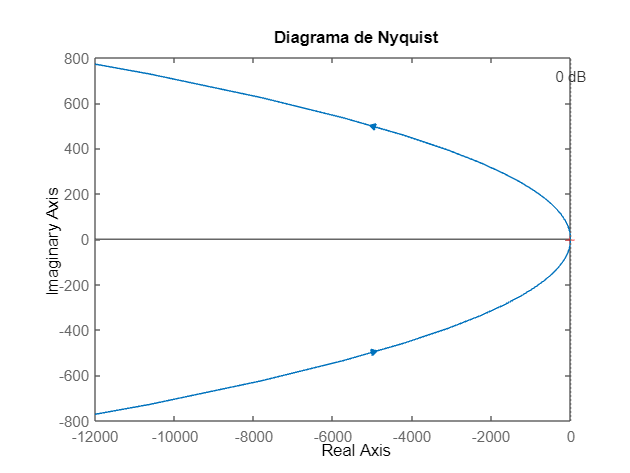

figure; nyquistplot(L); grid on; title('Diagrama de Nyquist');

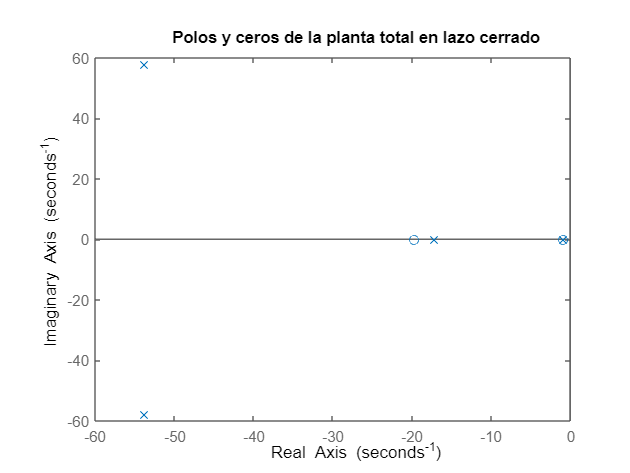


% Polos y ceros
figure; pzmap(FTc); title('Polos y ceros de la planta total en lazo cerrado');

[z,p,k] = zpkdata(FTc,'v');
disp('--- Polos del sistema en lazo cerrado ---');

--- Polos del sistema en lazo cerrado ---


disp(p);

 -53.8181 +57.8761i
 -53.8181 -57.8761i
 -17.1665 + 0.0000i
  -0.8540 + 0.0000i



Escalón de perturbación 

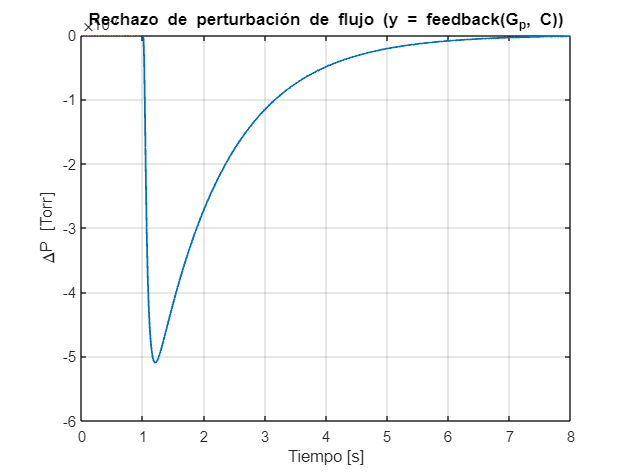

% --- Rechazo de perturbación de flujo (load disturbance en la planta) ---
% Transferencia correcta y robusta: y(s)/d(s) = Gp / (1 + Cpid*Gp) = feedback(Gp, Cpid)
T_d = feedback(Gp, Cpid);    % <— evita minreal y construye  Gp/(1+C*Gp)

% Perturbación más visible: escalón aplicado en t=1 s
t = 0:0.01:8;
d_amp = 5;                             % p.ej. 5 [Torr·L/s] (ajústalo a tu rango)
d = d_amp*(t >= 1);                    % escalón en t = 1 s

% Simulación
y_d = lsim(T_d, d, t);

figure; plot(t, y_d, 'LineWidth',1.2); grid on
title('Rechazo de perturbación de flujo (y = feedback(G_p, C))');
ylabel('\DeltaP [Torr]'); xlabel('Tiempo [s]');


% Chequeo: ganancia DC debe ser ~0 por la acción integral (rechazo en estado estacionario)
fprintf('dcgain(T_d) = %.4e (≈ 0 con integral)\n', dcgain(T_d));

dcgain(T_d) = 0.0000e+00 (≈ 0 con integral)



% Métrica rápida: pico de desviación por la perturbación
fprintf('Max |ΔP| ante d-step = %.4f Torr\n', max(abs(y_d)));

Max |ΔP| ante d-step = 0.0000 Torr


DISCRETIZACIÓN DEL LAZO CERRADO (para simulación digital)

% Parámetros de muestreo
Ts = 0.01;   % 10 ms (frecuencia de muestreo = 100 Hz)

% --- Polos y ceros del sistema continuo ---
[Z,P,K] = zpkdata(FTc,'v');
disp('Polos del sistema continuo:'), disp(P);

Polos del sistema continuo:
 -53.8181 +57.8761i
 -53.8181 -57.8761i
 -17.1665 + 0.0000i
  -0.8540 + 0.0000i



disp('Ceros del sistema continuo:'), disp(Z);

Ceros del sistema continuo:
  -19.6892
   -0.8363



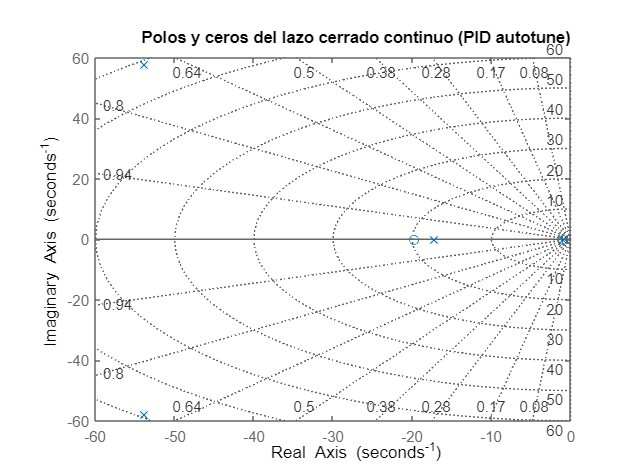


figure; pzmap(FTc); grid on;
title('Polos y ceros del lazo cerrado continuo (PID autotune)');

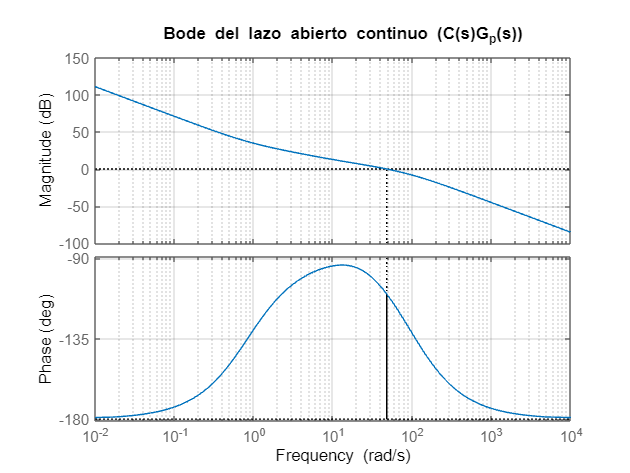


figure; margin(L); grid on;
title('Bode del lazo abierto continuo (C(s)G_p(s))');


%% --- Diferentes métodos de discretización del lazo cerrado ---
FTzoh      = c2d(FTc, Ts, 'zoh');
FTimpulse  = c2d(FTc, Ts, 'impulse');
FTtustin   = c2d(FTc, Ts, 'tustin')

FTtustin =
 
  0.08299 z^4 + 0.01557 z^3 - 0.1503 z^2 - 0.01532 z + 0.06755
  ------------------------------------------------------------
          z^4 - 2.829 z^3 + 3.026 z^2 - 1.5 z + 0.3045
 
Sample time: 0.01 seconds
Discrete-time transfer function.
Model Properties


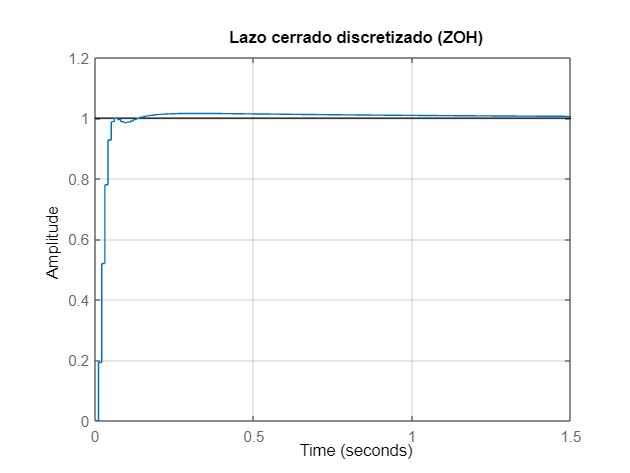

FTfoh      = c2d(FTc, Ts, 'foh');
FTmatched  = c2d(FTc, Ts, 'matched');

%% --- Análisis temporal de cada método ---
figure; step(FTzoh); grid on; title('Lazo cerrado discretizado (ZOH)');

stepinfo(FTzoh)

ans = struct with fields:
         RiseTime: 0.0300
    TransientTime: 0.0500
     SettlingTime: 0.0500
      SettlingMin: 0.9281
      SettlingMax: 1.0157
        Overshoot: 1.5683
       Undershoot: 0
             Peak: 1.0157
         PeakTime: 0.3100


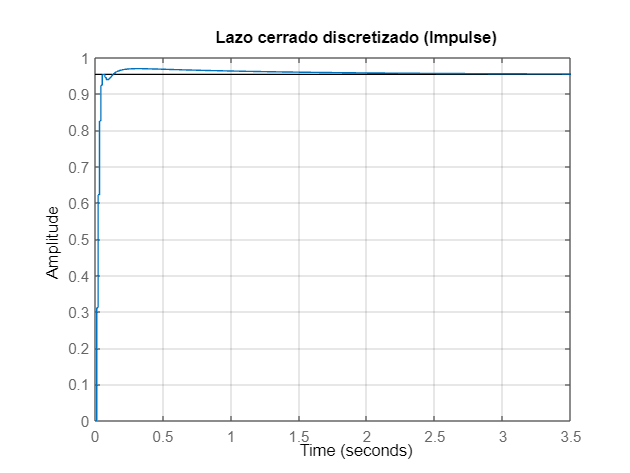


figure; step(FTimpulse); grid on; title('Lazo cerrado discretizado (Impulse)');

stepinfo(FTimpulse)

ans = struct with fields:
         RiseTime: 0.0300
    TransientTime: 0.0500
     SettlingTime: 0.0500
      SettlingMin: 0.9236
      SettlingMax: 0.9697
        Overshoot: 1.6439
       Undershoot: 0
             Peak: 0.9697
         PeakTime: 0.3100


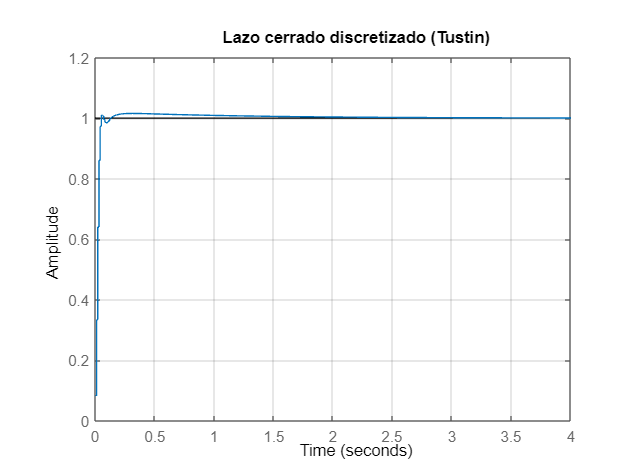


figure; step(FTtustin); grid on; title('Lazo cerrado discretizado (Tustin)');

stepinfo(FTtustin)

ans = struct with fields:
         RiseTime: 0.0300
    TransientTime: 0.0500
     SettlingTime: 0.0500
      SettlingMin: 0.9735
      SettlingMax: 1.0157
        Overshoot: 1.5690
       Undershoot: 0
             Peak: 1.0157
         PeakTime: 0.3100


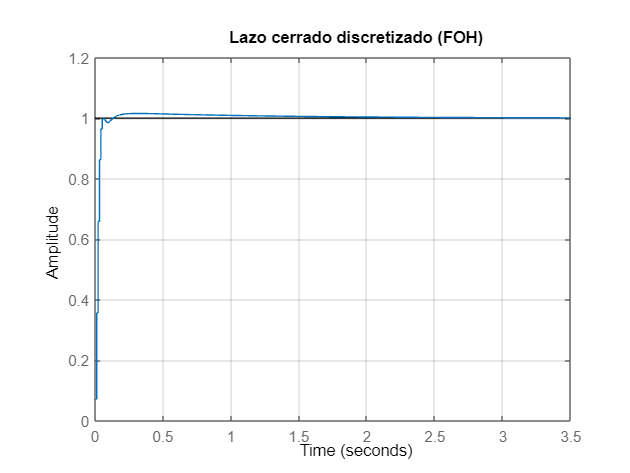


figure; step(FTfoh); grid on; title('Lazo cerrado discretizado (FOH)');

stepinfo(FTfoh)

ans = struct with fields:
         RiseTime: 0.0300
    TransientTime: 0.0500
     SettlingTime: 0.0500
      SettlingMin: 0.9639
      SettlingMax: 1.0157
        Overshoot: 1.5682
       Undershoot: 0
             Peak: 1.0157
         PeakTime: 0.3100


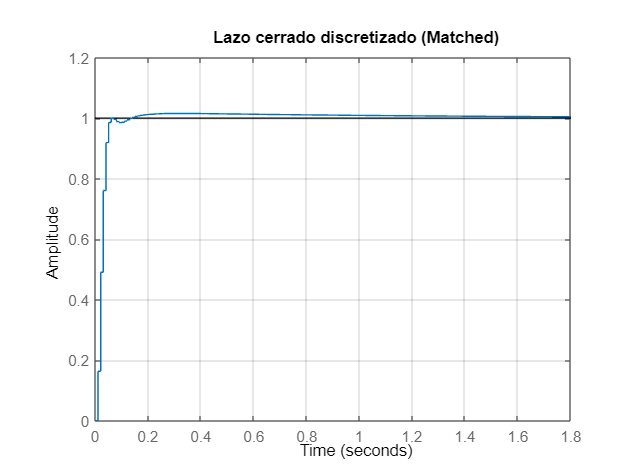


figure; step(FTmatched); grid on; title('Lazo cerrado discretizado (Matched)');

stepinfo(FTmatched)

ans = struct with fields:
         RiseTime: 0.0300
    TransientTime: 0.0500
     SettlingTime: 0.0500
      SettlingMin: 0.9191
      SettlingMax: 1.0157
        Overshoot: 1.5683
       Undershoot: 0
             Peak: 1.0157
         PeakTime: 0.3100


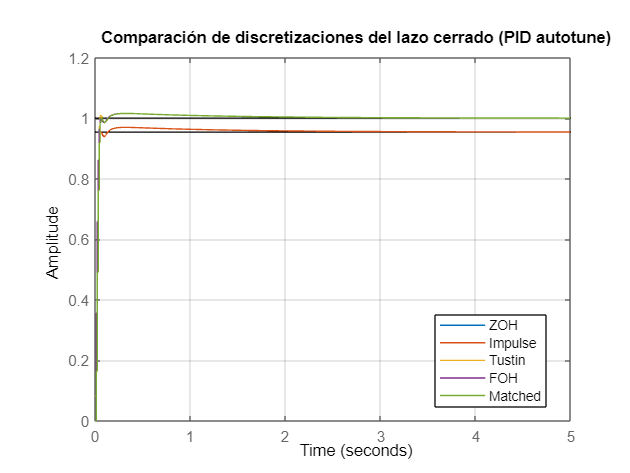


%% --- Comparación general ---
figure;
step(FTzoh, FTimpulse, FTtustin, FTfoh, FTmatched, 0:Ts:5);
legend('ZOH','Impulse','Tustin','FOH','Matched','Location','best');
grid on;
title('Comparación de discretizaciones del lazo cerrado (PID autotune)');

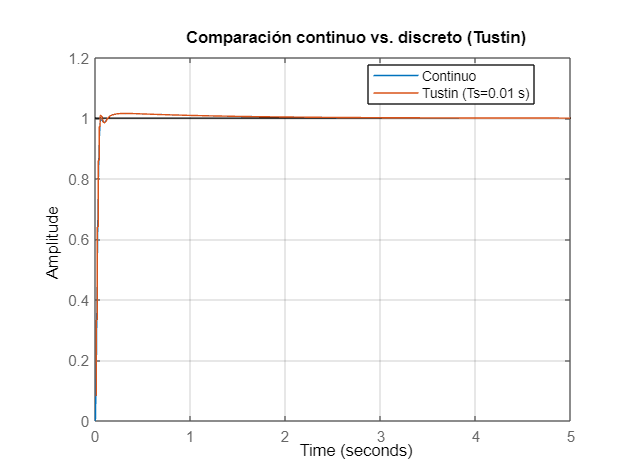


%% --- Comparación con el sistema continuo ---
figure;
step(FTc, FTtustin, 0:Ts:5);
legend('Continuo','Tustin (Ts=0.01 s)','Location','best');
grid on;
title('Comparación continuo vs. discreto (Tustin)');

PID Autotunning usando tustin 